# Workflow DES + Agua

**1. Importar los datos de viscosidad**

Visc_Rel=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Visc_Reline","VariableNamingRule","preserve")

Visc_Rel = 544×11 table
         DES             Set Type        Condition_Method       Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Viscosity(Pa.s)    Viscosity(cP)        Reference         DES mole fraction
    _____________    ________________    ________________    _____________    __________________    ________________    ______________    _______________    _____________    __________________    _________________

    {'ChCl-Urea'}    {'Computed'    }      {'Mean'    }      {'DES+Water'}            0                    1                303.15              0.511              511       

Gráfica de datos de viscosidad

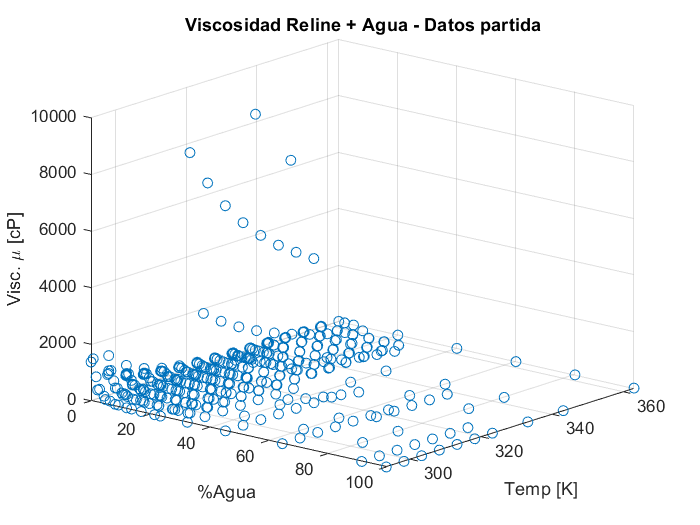

Masa_H2O_Rel=Visc_Rel.Mass_percent_Water*100;
Temp_Rel=Visc_Rel.("Temperature(K)");
Mu_Rel=Visc_Rel.("Viscosity(cP)");
figure, plot3(Masa_H2O_Rel,Temp_Rel,Mu_Rel,'o');
title('Viscosidad Reline + Agua - Datos partida'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Visc. \mu [cP]'),
view([40 20])

**2. División Conjuntos de Datos Entrenamiento y Prueba**

Matriz de datos de entrenamiento (2 predictores, 1 respuesta).

data1=[Masa_H2O_Rel,Temp_Rel,Mu_Rel];
n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 544
       NumTestSets: 1
         TrainSize: 436
          TestSize: 108

Datos de entrenamiento

idx_train=training(particion);
train_data_visc1=data1(idx_train,:)

train_data_visc1 = 	1.0e+03 *

         0    0.3332    0.0620
         0    0.3431    0.0370
         0    0.3631    0.0200
         0    0.3031    0.5360
         0    0.3131    0.2570
         0    0.3332    0.0630
         0    0.3431    0.0390
         0    0.3631    0.0210
         0    0.3131    0.2290
         0    0.3631    0.0190



Masa_H2O_Rel_train=train_data_visc1(:,1);
Temp_Rel_train=train_data_visc1(:,2);
Mu_Rel_train=train_data_visc1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_visc1=data1(idx_test,:)

test_data_visc1 = 	1.0e+03 *

         0    0.3031    0.5110
         0    0.3131    0.2430
         0    0.3031    0.4860
         0    0.3332    0.0610
         0    0.3431    0.0350
         0    0.3031    0.5273
         0    0.3332    0.0687
    0.0020    0.3031    0.2380
    0.0020    0.3631    0.0140
    0.0020    0.3031    0.2167



Masa_H2O_Rel_test=test_data_visc1(:,1);
Temp_Rel_test=test_data_visc1(:,2);
Mu_Rel_test=test_data_visc1(:,3);

**3. Regresión**

predictores_train=[Masa_H2O_Rel_train Temp_Rel_train];
regresion1 = fitlm(predictores_train,Mu_Rel_train)

regresion1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    ______    _______    _________

    (Intercept)     2527.3     769.73     3.2833    0.0011091
    x1             0.45158     1.7712    0.25495      0.79888
    x2             -6.9838     2.3727    -2.9434    0.0034211


Number of observations: 436, Error degrees of freedom: 433
Root Mean Squared Error: 974
R-squared: 0.0198,  Adjusted R-Squared: 0.0152
F-statistic vs. constant model: 4.37, p-value = 0.0133

Ecuacion

coef1=table2array(regresion1.Coefficients(1,1));
coef2=table2array(regresion1.Coefficients(2,1));
coef3=table2array(regresion1.Coefficients(3,1));

fprintf('Ecuación')

Ecuación

fprintf('Viscosidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Viscosidad= 2527.2625+(0.4516)*%Agua+(-6.9838)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Rel_train),max(Masa_H2O_Rel_train))

Rango de porcentaje: 0.00 % - 100.00 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Rel_train),max(Temp_Rel_train))

Rango de temperatura: 293.15 K - 363.15 K

Ajuste del modelo

x1fit=min(Masa_H2O_Rel_train):2:max(Masa_H2O_Rel_train);
x2fit=min(Temp_Rel_train):1:max(Temp_Rel_train);
[X1fit,X2fit]=meshgrid(x1fit,x2fit);

Y1fit=coef1+coef2*X1fit+coef3*X2fit;